# Task 1: Single spin-2 under a magnetic field

The problem of a single spin S=2 particle under a magnetic field ${\bf B}=(B_x,B_y,B_z)$ is described by the Zeeman Hamiltonian 


$$\mathcal{H} = - {\bf \mu} \cdot {\bf B} = -\gamma {\bf S} \cdot {\bf B} = -\gamma (B_x S_x + B_y S_y + B_z S_z)\,,$$


where $\gamma$ is the so-called gyromagnetic ratio of the particle, $B_x, B_y$ and $B_z$ are the Cartesian components of the field, and $S_x$, $S_y$ and $S_z$ are the quantum-mechanical operators that describe the spin polarization along the axes $x$, $y$ and $z$, respectively. 

# Subtask a

Write a few lines of code that deliver the matrix representation of the operators $S_x$, $S_y$ and $S_z$ in the '$S_z$-basis' $\{|S,M\rangle\}$. 

[Sx, Sy, Sz]=FetchSpinMatrices(2)

Sx =          0    1.0000         0         0         0
    1.0000         0    1.2247         0         0
         0    1.2247         0    1.2247         0
         0         0    1.2247         0    1.0000
         0         0         0    1.0000         0


Sy =    0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 - 1.2247i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 1.2247i   0.0000 + 0.0000i   0.0000 - 1.2247i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.2247i   0.0000 + 0.0000i   0.0000 - 1.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i


Sz =      2     0     0     0     0
     0     1     0     0     0
     0     0     0     0     0
     0     0     0    -1     0
     0     0     0     0    -2


# Subtask b

Write a few lines of code that deliver the matrix representation of $\mathcal{H}$ in the '$S_z$-basis', for ${\bf B}$ along the ${\bf y}$-axis and $\gamma B_y=1$. Solve the Schroedinger equation (eigenvalue matrix equation) to obtain the energy eigenvalues and the corresponding eigenstates of $\mathcal{H}$. Obtain the quantum mechanical expectation values of the three spin operators $S_x$, $S_y$ and $S_z$ in each eigenstate of $\mathcal{H}$.

%field in y direction so Bx = Bz = 0 and given that gammaBy = 1
Hamiltonian = -1 * (Sy)

Hamiltonian =    0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 1.2247i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.2247i   0.0000 + 0.0000i   0.0000 + 1.2247i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.2247i   0.0000 + 0.0000i   0.0000 + 1.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i


[V,D] = eig(Hamiltonian)

V =   -0.2500 + 0.0000i  -0.5000 + 0.0000i   0.6124 + 0.0000i   0.5000 + 0.0000i   0.2500 + 0.0000i
   0.0000 - 0.5000i   0.0000 - 0.5000i   0.0000 - 0.0000i   0.0000 - 0.5000i   0.0000 - 0.5000i
   0.6124 + 0.0000i  -0.0000 + 0.0000i   0.5000 + 0.0000i  -0.0000 + 0.0000i  -0.6124 + 0.0000i
   0.0000 + 0.5000i   0.0000 - 0.5000i   0.0000 - 0.0000i   0.0000 - 0.5000i   0.0000 + 0.5000i
  -0.2500 + 0.0000i   0.5000 + 0.0000i   0.6124 + 0.0000i  -0.5000 + 0.0000i   0.2500 + 0.0000i


D =    -2.0000         0         0         0         0
         0   -1.0000         0         0         0
         0         0    0.0000         0         0
         0         0         0    1.0000         0
         0         0         0         0    2.0000


E1 = V(:,1)

E1 =   -0.2500 + 0.0000i
   0.0000 - 0.5000i
   0.6124 + 0.0000i
   0.0000 + 0.5000i
  -0.2500 + 0.0000i


E2 = V(:,2)

E2 =   -0.5000 + 0.0000i
   0.0000 - 0.5000i
  -0.0000 + 0.0000i
   0.0000 - 0.5000i
   0.5000 + 0.0000i


E3 = V(:,3)

E3 =    0.6124 + 0.0000i
   0.0000 - 0.0000i
   0.5000 + 0.0000i
   0.0000 - 0.0000i
   0.6124 + 0.0000i


E4 = V(:,4)

E4 =    0.5000 + 0.0000i
   0.0000 - 0.5000i
  -0.0000 + 0.0000i
   0.0000 - 0.5000i
  -0.5000 + 0.0000i


E5 = V(:,5)

E5 =    0.2500 + 0.0000i
   0.0000 - 0.5000i
  -0.6124 + 0.0000i
   0.0000 + 0.5000i
   0.2500 + 0.0000i


E1expectationSx = E1'*Sx*E1

E1expectationSx = 0.0000e+00 - 2.7756e-17i

E2expectationSx = E2'*Sx*E2

E2expectationSx = 0.0000e+00 - 2.7756e-17i

E3expectationSx = E3'*Sx*E3

E3expectationSx = 0

E4expectationSx = E4'*Sx*E4

E4expectationSx = 0.0000e+00 - 2.7756e-17i

E5expectationSx = E5'*Sx*E5

E5expectationSx = 0.0000e+00 - 4.1633e-17i

E1expectationSy = E1'*Sy*E1

E1expectationSy = 2.0000

E2expectationSy = E2'*Sy*E2

E2expectationSy = 1.0000

E3expectationSy = E3'*Sy*E3

E3expectationSy = -7.7542e-32

E4expectationSy = E4'*Sy*E4

E4expectationSy = -1.0000

E5expectationSy = E5'*Sy*E5

E5expectationSy = -2.0000

E1expectationSz = E1'*Sz*E1

E1expectationSz = 2.7756e-17

E2expectationSz = E2'*Sz*E2

E2expectationSz = 4.4409e-16

E3expectationSz = E3'*Sz*E3

E3expectationSz = 2.1778e-17

E4expectationSz = E4'*Sz*E4

E4expectationSz = -3.3307e-16

E5expectationSz = E5'*Sz*E5

E5expectationSz = 3.3307e-16

# Subtask c

Vary the value of $\gamma B_y$, and obtain a plot of the energy spectrum vs $\gamma B_y$ in the range $\gamma B_y \in [-1, 1]$.

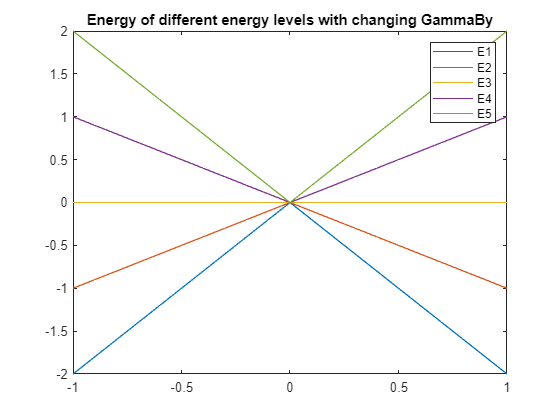

%for gammaBy = 1, energy = -2;1;2
E1 = [];
E2 = [];
E3 = [];
E4 = [];
E5 = [];

for gammaBy = -1:0.1:1;
    Hamiltonian = -1*(gammaBy)*Sy;
    Energy = eig(Hamiltonian);
    E1 = [E1 Energy(1)];
    E2 = [E2 Energy(2)];
    E3 = [E3 Energy(3)];
    E4 = [E4 Energy(4)];
    E5 = [E5 Energy(5)];
end;
y = -1:0.1:1;
plot(y,E1)
hold on
plot(y,E2)
hold on
plot(y,E3)
hold on
plot(y,E4)
hold on
plot(y,E5)
legend('E1','E2','E3','E4','E5')
title("Energy of different energy levels with changing GammaBy")
hold off

# Subtask d

Plot the $\textbf{ground state}$ expectation value of the operator $S_y$ vs $\gamma B_y$ in the range $\gamma B_y \in [-1, 1]$.

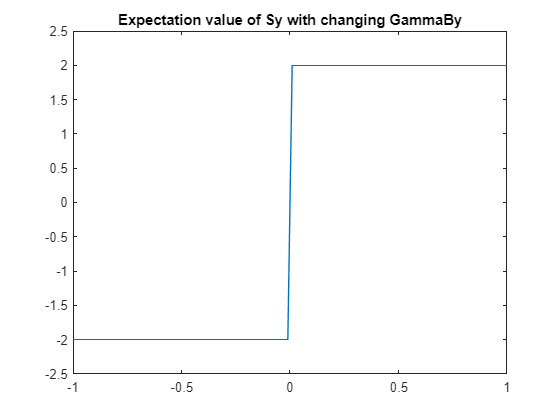

%ground state is where energy is minimum = E1
expectationSy = [];
for gammaBy = -1:0.01:1;
    Hamiltonian = -1*(gammaBy)*Sy;
    [V,D] = eig(Hamiltonian);
    E1 = V(:,1);
    E1expectationSy = E1' * Sy * E1;
    expectationSy = [expectationSy E1expectationSy];
end
expectationSy;
x = -1:0.01:1;
plot(x,expectationSy)
title("Expectation value of Sy with changing GammaBy")

Function for finding spin matracies as provided

function [Sx, Sy, Sz, Sp, Sm]=FetchSpinMatrices(S)

%sanity check
if rem(2*S,1)~=0; 
 disp('please provide an integer or half-integer value for S'); 
 return; 
end

dim=2*S+1; %dimension of Hilbert space

%initialize the matrices
Sx=zeros(dim,dim); Sy=zeros(dim,dim); Sz=zeros(dim,dim); Sp=zeros(dim,dim); Sm=zeros(dim,dim);


j=0;
for m=S:-1:-S; j=j+1;

 %Sz matrix
 Sz(j,j)=m;

 %Sp matrix
 f1=sqrt(S*(S+1)-m*(m+1));
 if f1~=0; 
  Sp(j-1,j)=f1; %matrix element between the bra <m+1| (corresponding to index j-1) and ket |m> (corresponding to index j)
 end

 %Sm matrix
 f2=sqrt(S*(S+1)-m*(m-1));
 if f2~=0; 
  Sm(j+1,j)=f2; %matrix element between the bra <m-1| (corresponding to index j+1) and ket |m> (corresponding to index j)
 end

end
Sx=(Sp+Sm)/2;
Sy=(Sp-Sm)/(2*complex(0,1));

return
end